Code to import and view image

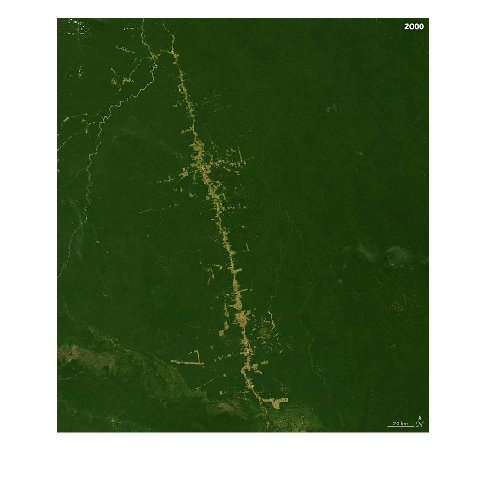

imshow("year2000.jpg")

Title("Nose")

Unrecognized function or variable 'Title'.

Trying to get matrix of values from image

I = imread("year2000.jpg")

I = 800×720×3 uint8 array
I(:,:,1) =

    40    39    37    38    39    39    37    35    45    28    29    50    58    44    35    40    40    37    36    35    31    30    42    59    58    31    32    40    21    24    45    51    54    21    44    24    31    38    38    28    32    43    48    42    36    34    33    30    29    29    30    31    31    30    30    29    33    35    36    36    35    36    38    41    35    37    39    39    37    37    40    43    47    47    47    48    48    49    50    50    44    45    47    48    48    46    44    43    44    43    43    44    45    44    42    39    41    41    40    40    38    36    35    33    33    30    29    32    33    31    32    35    34    34    35    35    35    35    36    36    39    39    39    35    32    32    35    39    33    37    39    37    32    29    32    35    34    33    33    33    33    33    33    33    32    32    32    33    34    35    36    37    31    32    33    33    31    31    32    33  

Trying to bit bin an image

A = kron([1,3,5; 2,4,8; 3,6,9], ones(2))

A =      1     1     3     3     5     5
     1     1     3     3     5     5
     2     2     4     4     8     8
     2     2     4     4     8     8
     3     3     6     6     9     9
     3     3     6     6     9     9


Running code to bin matrix A

s = size(A);
bs = [2 2]; % blocksize
B = reshape(A.',bs(1),s(1)/bs(1),[]);
B = reshape(permute(B,[1 3 2]),bs(1),bs(2),[]);
B = sum(sum(B,1),2);
B = reshape(B,s./bs)

B =      4    12    20
     8    16    32
    12    24    36
